# Introduction to neural networks: shallow neural networks

## Shallow neural networks

Now that we constructed a logistic regression model that performs forward and backward propagation, let's return back to the original model we wanted to build - the neural network with 1 hidden layer. We'll set the number of nodes in the hidden layer equal to 2. 

The schematic for the model we're training and a summary of the computations performed is shown below:

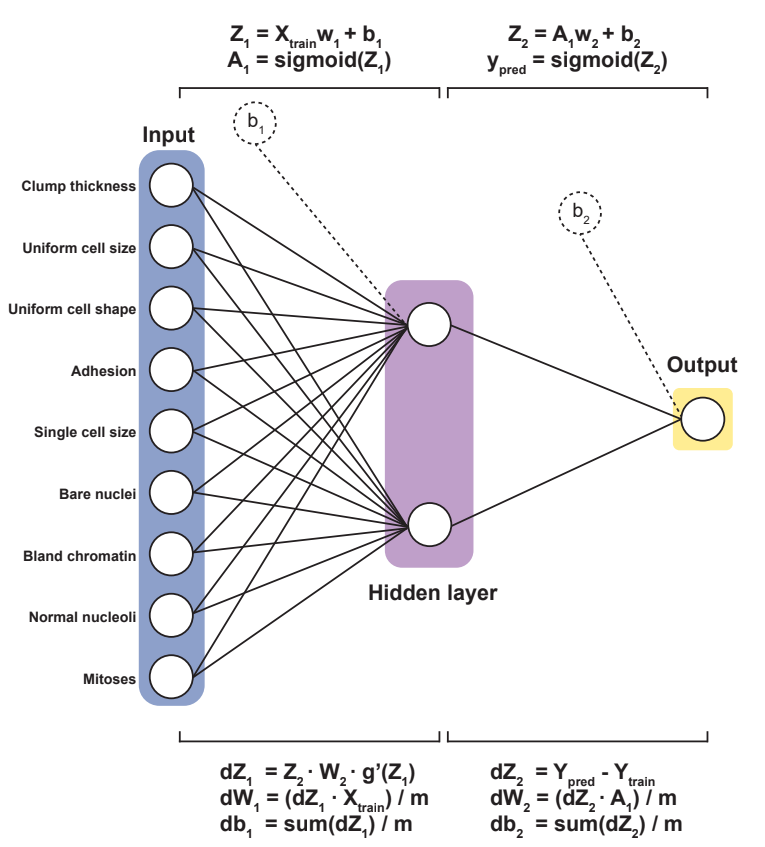

### Load breast cancer imaging dataset

First, let's load the breast cancer imaging dataset we used in the previous section.

clear all; rng(2);
load cancer_dataset.mat

% Initialize params for trainTestSplit
trainingSize = 0.8; randomstate = 2;

% Split the dataset into training and test sets.
[Xtrain, Ytrain, Xtest, Ytest] = ...
    trainTestSplit(cancerInputs', cancerTargets(1, :)', ...
    trainingSize, randomstate);

% Standardize the dataset with mean = 0 and standard deviation = 1. 
mu = mean(Xtrain); sigma = std(Xtrain);
Xtrain = (Xtrain - mu) ./ sigma; 
Xtest  = (Xtest - mu)  ./ sigma; % Use the same mu and sigma -> assume same distribution

### Forward propagation

First let's initialize some parameters and hyperparameters. This time, we'll have 4 parameters to compute: weights and biases between input and hidden layer `(w1, b1)`, and weights / biases between hidden and output layer `(w2, b2)`. 

% Intialize the hyperparameters 
numberOfHiddenNodes = 2; actFnc = 'Sigmoid';

% Intialize the weights and biases. 
w1 = randn([size(Xtrain, 2), numberOfHiddenNodes]) % Size of w1 should be number of features x number of hidden nodes

w1 =    -0.1741    1.4754
   -1.4407    0.4140
   -0.0709    0.4951
   -1.3681    2.1199
   -1.4625   -0.4965
   -0.0212    0.4568
    1.2875   -0.3635
   -2.7914    0.9546
   -1.3112    0.4000


b1 = randn(size(Xtrain, 1), 1)                     % Size should be number of obs x 1

b1 =    -0.5168
    1.0543
   -0.9014
    0.3487
   -0.0283
    0.3249
    0.3039
    0.4992
    0.0155
   -1.5946


#### First forward step from the input layer to the hidden layer

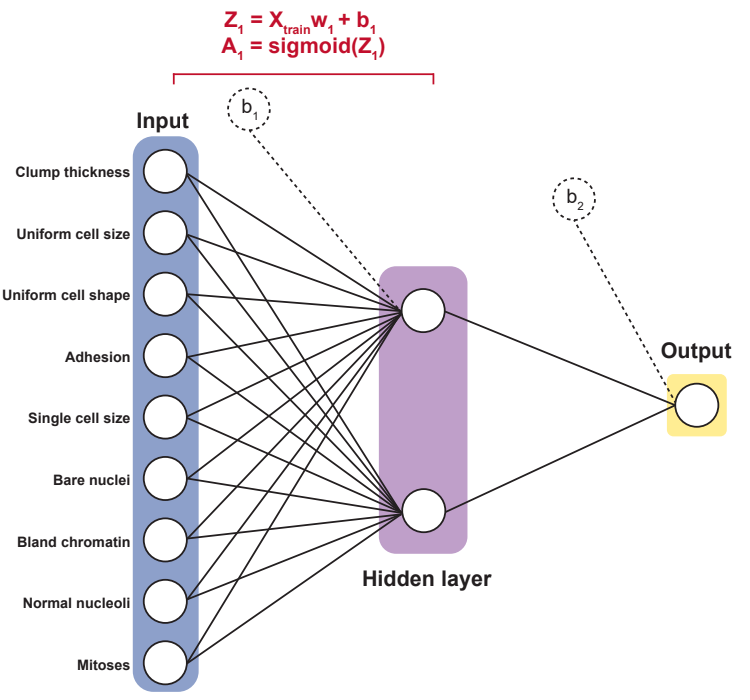

Note that Z1 and A1 are the linear combination of features and transformed features. Because we have 2 activation nodes, we have 2 engineered features. The computations for each step are shown below:


$${\mathit{\mathbf{Z}}}_1 ={\mathit{\mathbf{X}}}_{\mathbf{train}} {\mathit{\mathbf{w}}}_1 +{\mathit{\mathbf{b}}}_1$$


Z1 = Xtrain * w1 + b1

Z1 =     3.6998   -4.2524
    5.8156   -2.8351
    3.1298   -3.0658
   -7.0401    6.1924
    3.0049   -1.5801
    2.3786   -3.2112
  -15.3596    7.0886
    5.1368   -2.3428
    4.5914   -2.3027
   -9.8762    3.3865


${\mathit{\mathbf{A}}}_1 =g\left({\mathit{\mathbf{Z}}}_1 \right)$, where $g\left({\mathit{\mathbf{Z}}}_1 \right)=\textrm{sigmoid}\left({\mathit{\mathbf{Z}}}_1 \right)$ in this specific case.

A1 = activationFnc(Z1, actFnc)

A1 =     0.9759    0.0140
    0.9970    0.0555
    0.9581    0.0445
    0.0009    0.9980
    0.9528    0.1708
    0.9152    0.0387
    0.0000    0.9992
    0.9942    0.0876
    0.9900    0.0909
    0.0001    0.9673


#### The last forward step from the hidden layer to the output layer

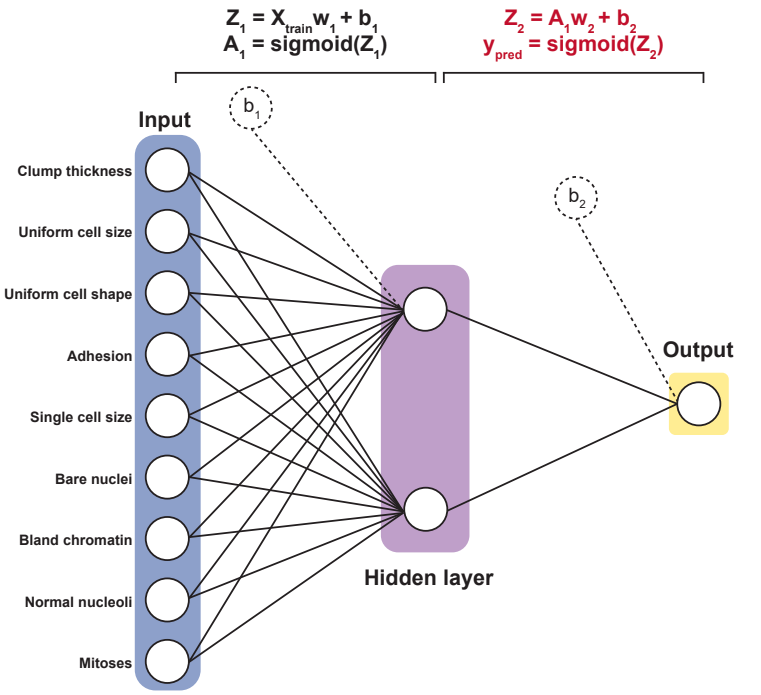

Now that we have the transformed values stored in `A1`, we'll use this data and transform it 1 more time using forward propagation. 

First, let's initialize the weights and biases. Note that because we're trying to output a single vector of predicted values, the column size of the weights must also be the same size as Ytrain.

w2 = randn([size(A1, 2), size(Ytrain, 2)]) % Size of w2 needs to be number of features in A1 x number of classes

w2 =    -1.5640
   -1.9588


b2 = randn(size(A1, 1), 1)                 % Size of b2 needs to be number of obs x 1

b2 =     0.4722
   -0.2378
    0.2750
   -3.0449
   -1.9323
    1.2590
   -1.8197
   -0.5824
   -1.0763
    1.6370


Finally, let's move 1 forward step from the hidden layer to the output layer. We'll use the same activation function we used in the previous step. In practice, we can use different activation functions in different neural network layers, which is allowed due to modularity of neural networks.


$${\mathit{\mathbf{Z}}}_2 ={\mathit{\mathbf{A}}}_1 {\mathit{\mathbf{w}}}_2 +{\mathit{\mathbf{b}}}_2$$


Z2 = A1 * w2 + b2

Z2 =    -1.0816
   -1.9058
   -1.3107
   -5.0011
   -3.7570
   -0.2483
   -3.7769
   -2.3089
   -2.8026
   -0.2578


Because this is the last step, the final transformed dataset is our predicted value `ypred`

${\mathit{\mathbf{y}}}_{\textrm{pred}} =g\left({\mathit{\mathbf{Z}}}_2 \right)$, where $g\left({\mathit{\mathbf{Z}}}_2 \right)=\textrm{sigmoid}\left({\mathit{\mathbf{Z}}}_2 \right)$ in this specific case.

ypred = activationFnc(Z2, actFnc)

ypred =     0.2532
    0.1295
    0.2124
    0.0067
    0.0228
    0.4383
    0.0224
    0.0904
    0.0572
    0.4359


 That's forward propagation with 1 hidden layer. Next, we need to evaluate the cost.

### Cost evaluation

To evaluate the cost, let's use the cross entropy loss function:


$$J=-\frac{1}{m}\sum_{i=1}^m \left\lbrack -{y_{\textrm{train}} }^{\left(i\right)} \log \left(y_{\textrm{pred}}^{\left(i\right)} \right)-\left(1-{y_{\textrm{train}} }^{\left(i\right)} \right)\log \left(1-y_{\textrm{pred}}^{\left(i\right)} \right)\right\rbrack$$


LossFunction = 'Log-Loss'; J = costFunction(Ytrain, ypred, LossFunction)

J = 1.3478

### Backward propagation

We went over the derivative terms for a single step of back propagation, and the computation from the outer layer to the hidden layer will be the same:

#### **Output layer to hidden layer**

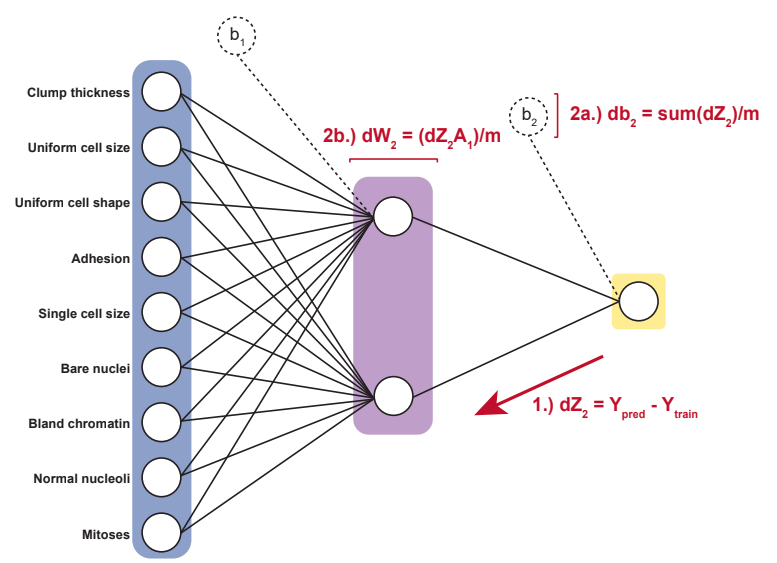

There are two main areas where the model can go wrong:

- 
$${\textrm{dZ}}_2 ={\mathit{\mathbf{Y}}}_{\textrm{pred}} -{\mathit{\mathbf{Y}}}_{\textrm{train}} \;$$


- ${\mathit{\mathbf{d}}\mathit{\mathbf{W}}}_2 =\frac{1}{m}\left({\mathbf{dZ}}_2 \cdot {{\mathbf{A}}_1 }^T \right)$;$\;{\;\textrm{db}}_2 =\frac{1}{m}\sum_{i=1}^n \left({\textrm{dZ}}_2 \right)$

First let's compute the error from the output ${\textrm{dZ}}_2 ={\mathit{\mathbf{Y}}}_{\textrm{pred}} -{\mathit{\mathbf{Y}}}_{\textrm{train}}$

dZ2 = ypred - Ytrain

dZ2 =    -0.7468
   -0.8705
   -0.7876
    0.0067
   -0.9772
   -0.5617
    0.0224
   -0.9096
   -0.9428
    0.4359


Next, we have to compute how much error our weights contributed to the overall error in proportion to ${\textrm{dZ}}_2$`.` $\frac{1}{m}$ normalizes our error term by the number of observations in the dataset: ${\mathit{\mathbf{d}}\mathit{\mathbf{W}}}_2 =\frac{1}{m}\left({\textrm{dZ}}_2 \cdot {{\mathbf{A}}_1 }^T \right)$

m = size(Xtrain, 1) % m = number of observations in training set

m = 559

dW2 = (1/m) .* (A1' * dZ2)

dW2 =    -0.4826
   -0.0317


Finally, we compute the error in the bias term, which is the sum of the errors from the output layer normalized based on the number of observations in the data: 


$${\;\textrm{db}}_2 =$$
 
$$\frac{1}{m}\sum_{i=1}^n \left({\textrm{dZ}}_2 \right)$$
 

db2  = (1/m) .* sum(dZ2, 2)

db2 =    -0.0013
   -0.0016
   -0.0014
    0.0000
   -0.0017
   -0.0010
    0.0000
   -0.0016
   -0.0017
    0.0008


#### **Hidden layer to input layer**

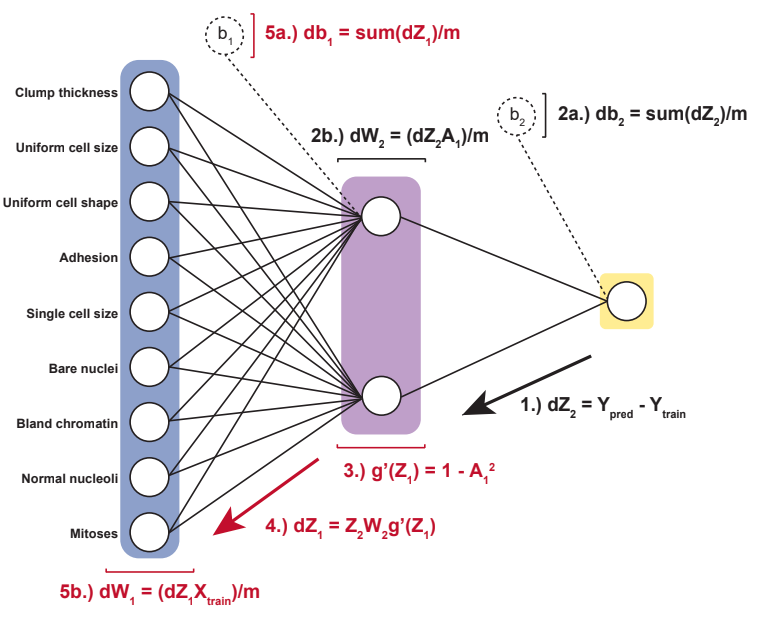

The computation for the hidden layer to the input layer will essentially be the same, except for computing ${\textrm{dZ}}_1$`.` This time, we need to compute the error generated from the activation function, $g^{\prime } \left({\mathit{\mathbf{Z}}}_1 \right)$. The three main areas where to model can generate errors are the following bulletpoints:

- $g^{\prime } \left({\mathit{\mathbf{Z}}}_1 \right):$ As noted earlier, the activation function does have its own error term $g^{\prime } \left({\mathit{\mathbf{Z}}}_1 \right)$. For the sigmoid activation function derivative term: $g^{\prime } \left({\mathit{\mathbf{Z}}}_1 \right)\;=\left(1-{{\mathit{\mathbf{A}}}_1 }^2 \right)$. 

- 
$${\textrm{dZ}}_1 ={{\mathit{\mathbf{W}}}_2 }^{\mathit{\mathbf{T}}} \cdot {\mathit{\mathbf{Z}}}_2 \cdot g^{\prime } \left({\mathit{\mathbf{Z}}}_1 \right)$$


- 
$${\mathit{\mathbf{d}}\mathit{\mathbf{W}}}_1 =\frac{1}{m}\left({\textrm{dZ}}_1 \cdot {{\mathit{\mathbf{X}}}_{\textrm{train}} }^{\mathit{\mathbf{T}}} \right);$$

$$\;{\textrm{db}}_1 =\frac{1}{m}\sum_{i=1}^n \left({\textrm{dZ}}_1 \right)$$


Note that the ReLU and leaky ReLU are nice in that there is no derivative! Instead, we can use the following rule sets:


$${g^{\prime } \left({\mathit{\mathbf{Z}}}_1 \right)}_{\mathrm{ReLU}} =\left\lbrace \begin{array}{cc}
1 & \mathrm{if}\;z_{\mathrm{ij}} >0\\
0 & \mathrm{if}\;z_{\mathrm{ij}} \le 0
\end{array}\right.$$



$${g^{\prime } \left({\mathit{\mathbf{Z}}}_1 \right)}_{\mathrm{Leaky}\;\mathrm{ReLU}} =\left\lbrace \begin{array}{cc}
1 & \mathrm{if}\;z_{\mathrm{ij}} >0\\
\varepsilon  & \mathrm{if}\;z_{\mathrm{ij}} \le 0
\end{array}\right.$$


Let's repeat the final step of back propagation, using the sigmoid activation function gradient: ${\mathbf{dZ}}_1 ={{\mathit{\mathbf{W}}}_2 }^{\mathit{\mathbf{T}}} \cdot {\mathit{\mathbf{Z}}}_2 \cdot g^{\prime } \left({\mathit{\mathbf{Z}}}_1 \right)$

dZ1  = (w2 * dZ2') .* (1 - A1.^2)'

dZ1 =     0.0557    0.0081    0.1010   -0.0105    0.1409    0.1427   -0.0350    0.0166    0.0295   -0.6817    0.0149    0.6028    0.0237    0.0620    0.0190   -0.1775   -0.0922    0.0103   -0.8669    0.0709    0.1342    0.0290    0.6890    0.0138   -0.0679   -0.0005    0.2191    0.0627    0.0098   -0.2627    0.0384   -0.0511    0.0172    0.0629   -0.3497    0.0028    0.0454    0.1462   -0.0708    0.0372    0.7232    0.0273    0.0986    0.0130    0.0773    0.1545   -0.0793   -0.3924   -0.9118   -0.2527
    1.4625    1.7000    1.5398   -0.0001    1.8583    1.0987   -0.0001    1.7681    1.8316   -0.0550    1.4242    0.7550    1.8046    1.0078    1.9205   -0.0000   -0.0041    1.0144   -0.1446    1.2774    1.6349    1.6271    1.3415    1.6111   -0.0014   -0.0693    1.5341    1.3710    1.4931   -0.0000    1.5621   -0.0000    1.8208    1.7488   -0.0347    1.7563    1.7292    1.8362   -0.0026    1.7192    0.9167    1.5271    1.8267    1.0048    1.5686    1.8361   -0.0000   -0.0190   -0.0023   

Next, let's compute the gradient for ${\mathit{\mathbf{W}}}_1 :$ ${\textrm{dW}}_1 =\frac{1}{m}\left({\textrm{dZ}}_1 \cdot {{\mathit{\mathbf{X}}}_{\textrm{train}} }^{\mathit{\mathbf{T}}} \right)$ 

dW1  = (1/m) .* Xtrain' * dZ1'

dW1 =    -0.0906   -0.5411
   -0.1146   -0.6082
   -0.1168   -0.6057
   -0.0759   -0.5245
   -0.0898   -0.5185
   -0.1189   -0.6111
   -0.1281   -0.5569
   -0.1005   -0.5362
   -0.0808   -0.2874


Finally, we need to compute the cost for the biases: $\;{\textrm{db}}_1 =\frac{1}{m}\sum_{i=1}^n \left({\textrm{dZ}}_1 \right)$

db1  = (1/m) .* sum(dZ1', 2)

db1 =     0.0027
    0.0031
    0.0029
   -0.0000
    0.0036
    0.0022
   -0.0001
    0.0032
    0.0033
   -0.0013


### Gradient descent

Now that we computed the gradients, let's compute the updated weights (${\mathit{\mathbf{W}}}_1 \;\textrm{and}\;{\mathit{\mathbf{W}}}_2$) and biases (${\mathit{\mathbf{b}}}_1 \;\textrm{and}\;{\mathit{\mathbf{b}}}_2$) using gradient descent:

#### Update weights from output layer to hidden layer:

 
$$\begin{array}{l}
W_2 \;\;=W_2 \;\;-\left(\mathrm{learning}\;\mathrm{rate}\cdot dW_2 \right)\\
b_2 \;\;\;=\;b_2 \;\;-\left(\mathrm{learning}\;\mathrm{rate}\cdot db_2 \right)
\end{array}$$


learning_rate = 0.05;
w2 = w2 - (learning_rate .* dW2)

w2 =    -1.5398
   -1.9572


b2 = b2 - (learning_rate .* db2)

b2 =     0.4722
   -0.2378
    0.2750
   -3.0449
   -1.9323
    1.2590
   -1.8197
   -0.5823
   -1.0762
    1.6370


#### Update weights from hidden layer to input layer:

 
$$\begin{array}{l}
W_1 \;\;=W_1 \;\;-\left(\mathrm{learning}\;\mathrm{rate}\cdot dW_1 \right)\\
b_1 \;\;\;=\;b_1 \;\;-\left(\mathrm{learning}\;\mathrm{rate}\cdot db_1 \right)
\end{array}$$


w1 = w1 - (learning_rate .* dW1)

w1 =    -0.1696    1.5024
   -1.4349    0.4444
   -0.0650    0.5254
   -1.3643    2.1461
   -1.4580   -0.4706
   -0.0152    0.4874
    1.2940   -0.3356
   -2.7864    0.9814
   -1.3072    0.4144


b1 = b1 - (learning_rate .* db1)

b1 =    -0.5169
    1.0542
   -0.9015
    0.3487
   -0.0285
    0.3248
    0.3039
    0.4990
    0.0154
   -1.5945


We've computed one full epoch for a shallow neural network! The next step in training the neural network is recursive optimization for several epochs.

## Optimizing the neural network for binary classification

Now that we have all the steps required to train, evaluate, and optimize a shallow neural network, we would iterate this until the cost value reaches a minimum. To save space for iteratively running the shallow neural network we just wrote, we created an accessory function `SNN.` It has modularized the three steps we previously performed: forward propagation, evaluating the cost, and back propagation. The docstring is provided below:

### Training and optimizing the shallow neural network

Let's now use this function to train a neural network using the cancer dataset:

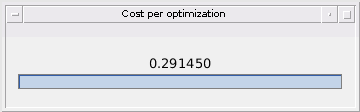

model = struct with fields:
     ypred: [559×1 double]
         J: [500×1 double]
        w2: [2×1 double]
        b2: [559×1 double]
        w1: [9×2 double]
        b1: [559×1 double]
    actFnc: 'Sigmoid'


% Specify hyperparameters to train the model and store in structure
hyperparameters.numOfActiveNodes = 2;   hyperparameters.alpha = 0.05;
hyperparameters.epoch            = 500; hyperparameters.actFnc = 'Sigmoid';
hyperparameters.randomstate      = 2;

% Train the shallow neural network model
model = SNN(Xtrain, Ytrain, hyperparameters)

### Evaluating the costs

Now that we have a trained model, let's evaluate the results. First, let's plot the cost with respect to the number of iterations we made in the model:

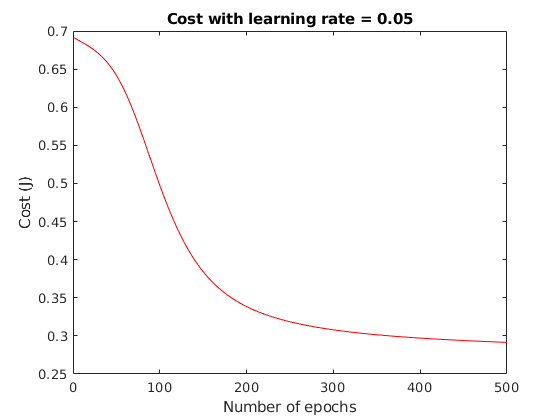

figure; epoch = 500;
plot(1:epoch, model.J, 'color', 'r');
title('Cost with learning rate = 0.05');
xlabel('Number of epochs'); ylabel('Cost (J)');
saveas(gcf, 'SNNJCurve.fig')

### Benchmarking the shallow neural network using 5-fold cross validation

We'll benchmark our shallow neural network using 2 activation nodes in the hidden layer. We'll perform 5-fold cross validation, and compare our results against the logistic regression classifier.

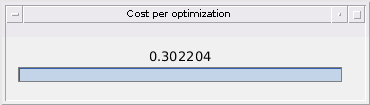

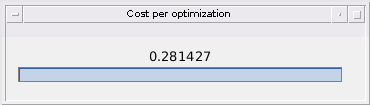

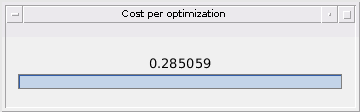

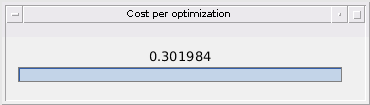

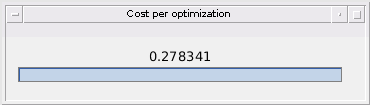

nnCM = struct with fields:
                     cm: [2×2 double]
           NormalizedCM: [2×2 double]
    malignant_precision: 0.9268
       benign_precision: 0.9589
       malignant_recall: 0.9744
          benign_recall: 0.9859
       average_accuracy: 0.9643


% Neural network 5-fold cross validation
kfold = 5; type = 'SNN';
trainingSize = 0.8; randomState = 2;
nnCM = crossValidate(Xtrain, Ytrain, Xtest, Ytest, ...
                            hyperparameters, kfold, type)

% Show results from logistic regression cross validation 
load logisticRegressionResults.mat
logRegressCV

logRegressCV = struct with fields:
                     cm: [2×2 double]
           NormalizedCM: [2×2 double]
    malignant_precision: 0.8537
       benign_precision: 0.9211
       malignant_recall: 0.9722
          benign_recall: 0.9859
       average_accuracy: 0.9375


% Load the logistic regression cross validation confusion matrix
openfig('logRegressCM.fig', 'visible')

ans =   Figure (2) with properties:

      Number: 2
        Name: ''
       Color: [1 1 1]
    Position: [2235 1622 560 420]
       Units: 'pixels'

  Show all properties


title('Confusion matrix from logistic regression 5-fold cross validation');
labels = {'Malignant', 'Benign'};

### Plot the neural network confusion matrix from 5-fold cross validation and benchmark against logistic regression 

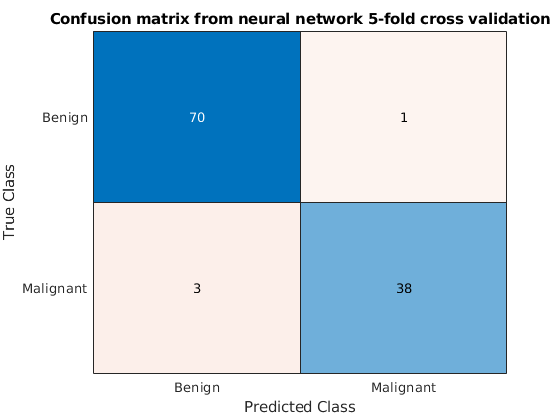

cm = nnCM.cm;
confusionchart(cm, labels);
title('Confusion matrix from neural network 5-fold cross validation');

TP  = cm(1, 1); FP = cm(1, 2); FN = cm(2, 1); TN  = cm(2, 2);
malignant_precision = (TP) / (TP + FP)

malignant_precision = 0.9268

malignant_recall    = (TP) / (TP + FN)

malignant_recall = 0.9744

benign_precision    = (TN) / (TN + FP)

benign_precision = 0.9589

benign_recall       = (TN) / (TN + FN)

benign_recall = 0.9859

average_accuracy    = sum(diag(cm)) / sum(cm, 'all')

average_accuracy = 0.9643

We are able to show that the neural network beats the logistic regression classifier. 

Now that we have demonstrated how neural networks operate under the hood, let's discuss how to use the built-in tools MATLAB provides not only for shallow neural networks, but for extending our computations to deep neural networks.

## Summary

We constructed a shallow neural network from scratch and benchmarked a logistic regression classifier against the shallow neural network using the breast cancer imaging dataset. 

In the next lecture, we will use MATLAB's Deep Learning Toolbox to train a shallow neural network, and deep neural network.

### Built-in MATLAB functions

`confusionmat:             `Automatically computes a confusion matrix for each class.

`confusionchart`:                         Plots the confusion matrix from `confusionmat`

### Custom MATLAB functions

`trainTestSplit:           `Splits an input ($X$) and output ($Y$) dataset into a training $\left(X_{\textrm{train}} {,\;Y}_{\textrm{train}} \right)$ and testing $\left(X_{\textrm{test}} {,\;Y}_{\textrm{test}} \right)$ dataset

`activationFnc:            `Transforms the dataset using a non-linear function.

`costFunction:`                            Computes the cost value from the model.

`crossValidate:`                          Performs k-fold cross validation.

`SNN:`                                               Trains a shallow neural network.